# Creating and Training a CNN to Classify Traffic Signs

For the Week 1 Project, you will:

- Prepare the traffic signs dataset for training

- Create a simple CNN

- Train the model to classify traffic signs

- Evaluate your trained model on test data

After you have finished, please proceed to the **"Project: Classifying Traffic Signs with a Simple CNN" **assessment to answer questions about your results.

## Prepare Your Data for Training

Inside the "Traffic Signs" folder, the data is already separated into Train and Test folders. 

Create an image datastore from the training dataset named `imdsSigns`:

% Select the location of the training data set:
filename = "D:\Coursera\Deep Learning for Computer Vision\Data\Traffic Signs\Train";
imdsSigns = imageDatastore(filename, "IncludeSubfolders",true,"LabelSource",'foldernames');


Use 80% of your data for training, leaving the remaining images for validation. Make sure to randomize which images are assigned to the validation set.

[imdsTrain, imdsValidation] = splitEachLabel(imdsSigns, 0.8,'randomized');


## Preview the Training Data

Before you dive into building your network architecture, it's worth familiarizing yourself with the images in this data set. 

Run this section several times to preview some of the training data:

img = read(imdsSigns);
size(img)

ans =     32    32     3


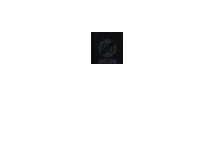

imshow(img)

Notice how many of the images are small, dark, blury, or otherwise difficult to see. 

All images are in RGB format, with sizes  $m \times n \times 3$, but they have a range of different sizes. Before you can train, you will have to resize these images to match the image input layer.

## Define the Network Architecture

Open the Deep Network Designer App to create and export a network with the following layers:

- `imageInputLayer`

- `convolution2dLayer`

- `reluLayer`

- `maxPooling2dLayer`

- `fullyConnectedLayer`

- `softmaxLayer`

- `classificationLayer`

Make sure you specify the correct `OutputSize` for `fullyConnectedLayer`.

% Insert the code generated from the Deep Network Designer App:
layers = [
    imageInputLayer([128 128 3], 'Name', 'input')
    convolution2dLayer([3 3], 32, 'Padding', 'same', 'Name', 'conv')
    reluLayer('Name', 'relu')
    maxPooling2dLayer([5 5], 'Name','maxpool','Padding', 'same')
    fullyConnectedLayer(9, 'Name', 'fc')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classoutput')];


## Resize Your Training Data

Resize the training and validation data to match the `InputSize` that you set above:

augTrain = augmentedImageDatastore([128 128], imdsTrain)

augTrain =   augmentedImageDatastore with properties:

           MiniBatchSize: 128
         NumObservations: 720
        DataAugmentation: 'none'
      ColorPreprocessing: 'none'
              OutputSize: [128 128]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


augVal = augmentedImageDatastore([128 128], imdsValidation)

augVal =   augmentedImageDatastore with properties:

           MiniBatchSize: 128
         NumObservations: 180
        DataAugmentation: 'none'
      ColorPreprocessing: 'none'
              OutputSize: [128 128]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


## Setting the Training Options

Finally, set your training options. You'll investigate training options in more detail later in this course. For now, use the same options as you saw in the video:

- Set the solver to `"adam"`

- Include the validation data you set aside earlier

- Set the Shuffle option to `"every-epoch"`

- Set the Plots option to `"training-progress"`

% Insert code to set the training options:
opts = trainingOptions('adam', 'ValidationData',augVal,'Shuffle','every-epoch', 'Plots',"training-progress")

opts =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.9000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 1.0000e-03
     LearnRateScheduleSettings: [1×1 struct]
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: Inf
                     MaxEpochs: 30
                 MiniBatchSize: 128
                       Verbose: 1
              VerboseFrequency: 50
                ValidationData: [1×1 augmentedImageDatastore]
           ValidationFrequency: 50
            ValidationPatience: Inf
                       Shuffle: 'every-epoch'
                CheckpointPath: ''
          ExecutionEnvironment: 'auto'
                    WorkerLoad: []
                     OutputFcn: []
                         Plots: 'training-progress'
                Sequence

## Train the Network

It's finally time to train your network! 

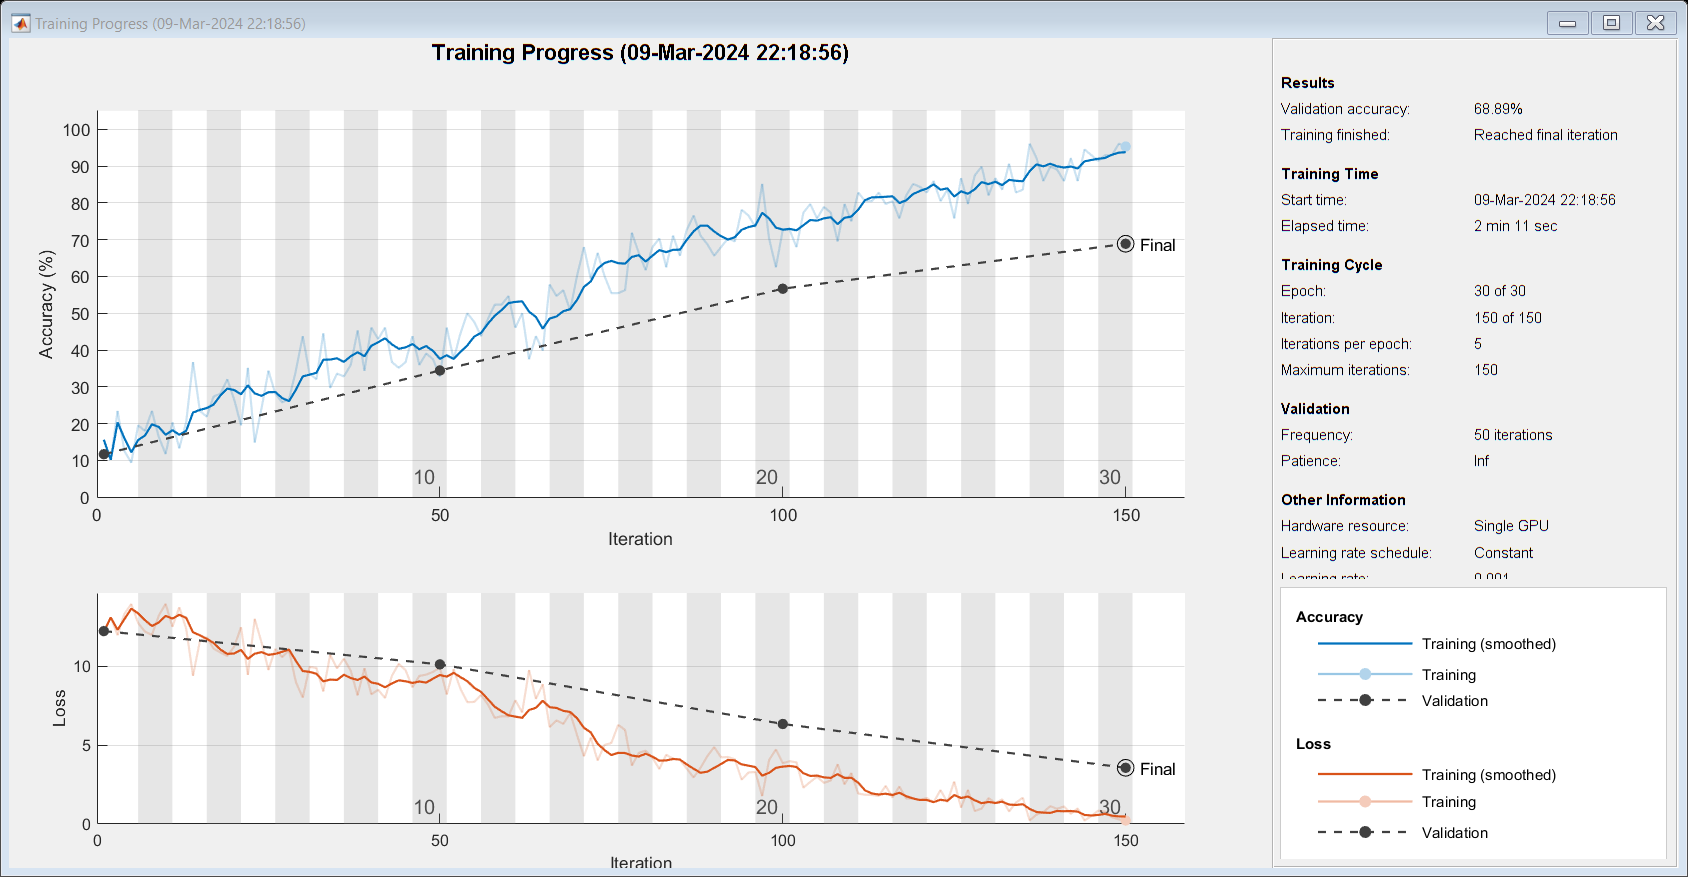

Training on single GPU.


Initializing image normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:29 |       15.63% |       11.67% |      12.1738 |      12.2167 |          0.0010 |
|      10 |          50 |       00:01:08 |       32.81% |       34.44% |       9.9053 |      10.1095 |          0.0010 |
|      20 |         100 |       00:01:40 |       72.66% |       56.67% |       3.8449 |       6.3338 |          0.0010 |
|      30 |         150 |       00:02:11 |       95.31% |       68.89% |       0.2211 |       3.5593 |          0.0010 

net =   SeriesNetwork with properties:

    Layers: [7×1 nnet.cnn.layer.Layer]


% Insert code to train your network:
net = trainNetwork(augTrain, layers, opts)

Training will likely take about 20 minutes using a CPU.

## Performance on Test Data

Once you have trained your network, you should examine its performance on your test data.

Don't forget to resize your images to match the expected input size for your trained network:

filenameTest = "D:\Coursera\Deep Learning for Computer Vision\Data\Traffic Signs\Test";
imdsTest = imageDatastore(filenameTest, "IncludeSubfolders",true,"LabelSource",'foldernames');

augTest = augmentedImageDatastore([128 128], imdsTest)

augTest =   augmentedImageDatastore with properties:

           MiniBatchSize: 128
         NumObservations: 288
        DataAugmentation: 'none'
      ColorPreprocessing: 'none'
              OutputSize: [128 128]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


Finally, use your test data to evaluate your trained network, including calculating the test accuracy and creating a confusion chart. You may need to click the arrow and open your confusion charts in the figure window to see them well:

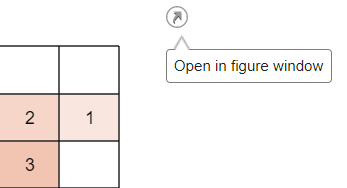

% Classify your test data:

testPreds = classify(net, augTest)

testPreds = 288×1 categorical array
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     Speed Limit 60 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     Speed Limit 100 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     Speed Limit 100 
     Speed Limit 100 
     Speed Limit 100 
     Speed Limit 100 
     Speed Limit 100 
     Speed Limit 100 
     Speed Limit 120 
     Speed Limit 100 
     Speed Limit 100 
     Speed Limit 100 
     Speed Limit 100 
     Speed Limit 80

% Compute the test accuracy and create a confusion chart:

testAccuracy = nnz(testPreds == imdsTest.Labels)/length(testPreds)

testAccuracy = 0.6632

While not perfect, this network performs surprisingly well considering the limited data set and the relatively simple architecture of your neural network. Later in this course, you will see how to achieve much better accuracy and loss values for this dataset.

Once you have completed this reading, proceed to the "Week 1 Project: Classifying Traffic Signs with a Simple CNN" quiz. You may want to keep this completed live script open as a reference as you answer questions about your results.

*Copyright 2024 The MathWorks, Inc.*